
%% Start
clc;
clear all;
close all;

N = 1000;       % Number of samples
Bits = 2;      % For PSK modulation    
SNR = 20;       % Noise level

h = [0.26 0.93 0.26];           %  impulse response

data = randsrc(1,N,0:1)        % Random index for input data

data =      0     1     1     0     1     1     1     0     0     0     1     1     0     0     0     0     1     1     0     1     1     1     0     1     0     1     0     1     1     0     1     0     0     0     1     1     0     0     0     1     1     0     1     0     0     1     1     1     0     0


x = -(real(pskmod(data,Bits))) % Phase shit keying (PSK) modulation

x =     -1     1     1    -1     1     1     1    -1    -1    -1     1     1    -1    -1    -1    -1     1     1    -1     1     1     1    -1     1    -1     1    -1     1     1    -1     1    -1    -1    -1     1     1    -1    -1    -1     1     1    -1     1    -1    -1     1     1     1    -1    -1


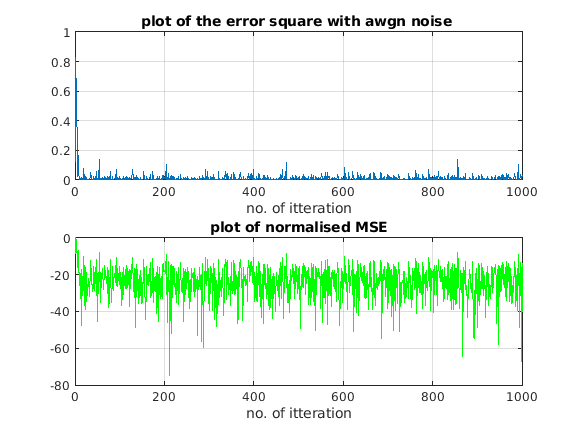

r = filter(h,1,x);              % Input passed trought system(h)
d = awgn(r, SNR);               % Addition of white gaussian noise of decined SNR


B = zeros(size(h));             % Initial weights of RLS
z=[];

%% RLS Parameters
p=2;
lamda=1;
sigma=1;
Wrls = B';                     % Initial weights of RLS
P=(sigma^-1)*eye(p+1);
U = zeros(size(Wrls));         % Input frame length of RLS
MSE_RLS=0;

for n = 1 : N
                 
%% RLS
        U(2:end,1) = U(1:end-1,1);  % Shifting of frame window
        U(1,1) = x(n);              % Input of RLS
        y(n) = U'*Wrls;                             % Output of RLS
        e(n) = d(n) - y(n);                     % Instantaneous error of RLS
        g(:,n)=P*U*((lamda + U'*P*U).^-1);          % Gain vector
        P=(lamda^-1)*P - g(:,n)*U'*(lamda^-1)*P;    % RLS intermediate term
        Wrls = Wrls + e(n)*g(:,n); % Weight update rule of RLS
        se=e.^2;     
end

z=[z,se];
subplot(211);
plot(se);
xlabel('no. of itteration');
title('plot of the error square with awgn noise ');
grid on ;
nmse=z/max(z);
subplot(212);
plot(10*log10(nmse),'g');
title('plot of normalised MSE');
xlabel('no. of itteration');
grid on ;